filename='x2.wav'

filename = 'x2.wav'

[y, fs]=audioread(filename);
samples=[1,length(y)];
[y10,fs] = audioread(filename,samples);
%soundsc(y10,fs);
audiowrite('originalLjudfil.wav',y10(:,1),fs);



%skapar alla positioner

Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T000_P000.wav', 'result0.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T015_P000.wav', 'result15.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T030_P000.wav', 'result30.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T045_P000.wav', 'result45.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T060_P000.wav', 'result60.wav'); %5
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T075_P000.wav', 'result75.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T090_P000.wav', 'result90.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T105_P000.wav', 'result105.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T120_P000.wav', 'result120.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T135_P000.wav', 'result135.wav'); %10
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T150_P000.wav', 'result150.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T165_P000.wav', 'result165.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T180_P000.wav', 'result180.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T195_P000.wav', 'result195.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T210_P000.wav', 'result210.wav'); %15
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T225_P000.wav', 'result225.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T240_P000.wav', 'result240.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T255_P000.wav', 'result255.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T270_P000.wav', 'result270.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T285_P000.wav', 'result285.wav'); %20
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T300_P000.wav', 'result300.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T315_P000.wav', 'result315.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T330_P000.wav', 'result330.wav');
Convolutionreverb('originalLjudfil.wav', 'IRC_1017_C_R0195_T345_P000.wav', 'result345.wav'); %24

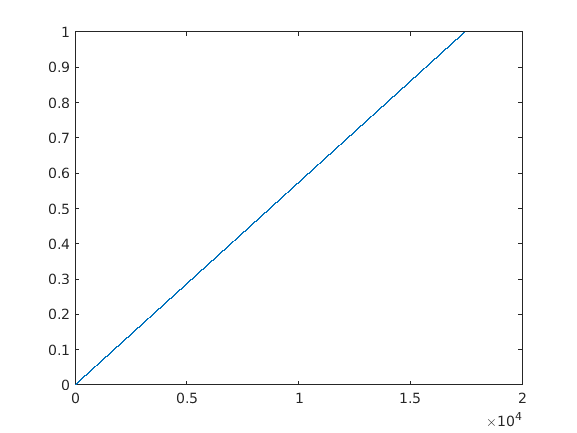



%pre-loop preparations

 filename="result0.wav";
        [y, fs1]=audioread(filename);
        samples1=[1, round(length(y)/24)];
        [y1,fs1] = audioread(filename,samples1);


t=linspace(0, 1, length(y1)); %linjär övergång för att slippa dämpad/ökad amplitud (fås om icke-linjär)
ampFadeIn= t;
ampFadeIn1 = ampFadeIn(:);

ampFadeOut = 1-t;
ampFadeOut1 = ampFadeOut(:);

plot(ampFadeIn);
hold off

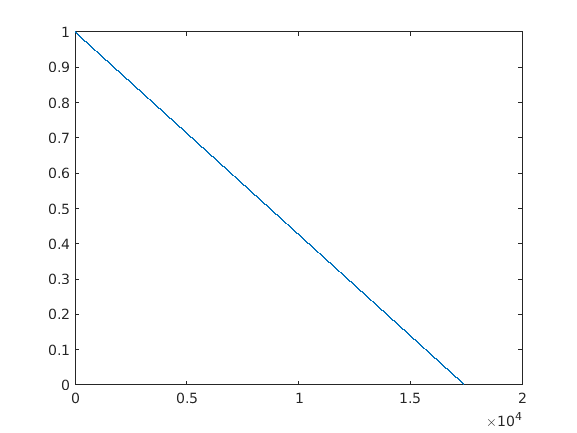

plot(ampFadeOut);


fadeout=y1;
length(fadeout)

ans = 17438

fadein=y1;

%loop

y4=zeros(size(y1));

x=0; %x bestämmer hur långt in i filen vi börjar

for nr=15:15:345
    %här klipps filerna upp
    %nr bestämmer vilken av positionsfilerna som används. nr=0 -> första filen, nr=1->andra, 
    % nr=3-> tredje...
    
        filename="result"+(nr-15)+".wav";
        [y, fs1]=audioread(filename);
        samples1=[round(x*length(y)/24)+1, round((x+1)*length(y)/24)];
        [y1,fs1] = audioread(filename,samples1);
        
        
        filename="result"+nr+".wav";
        [y, fs2]=audioread(filename);
        samples2=[round(x*length(y)/24)+1, round((x+1)*length(y)/24)];
        [y2,fs2] = audioread(filename,samples2);
        
        x=x+1; % ökar x -> börja längre in i nästa filpar, så inget ljudstycke repeteras.
      
        %z gör så att det funkar oavsett fil, både x1,x2 o drift går bra
        z = length(y1);
        if length(y1) > length(ampFadeOut)
             z = length(ampFadeOut);
        end

    for sample = 1:z %själva fadingen
        fadeout(sample,1)=y1(sample,1)*ampFadeOut1(sample,1);
        fadeout(sample,2)=y1(sample,2)*ampFadeOut1(sample,1); %om man har en stereofil (typ drift.wav)
                                                              %  så fadar man bägge kanaler
        
        fadein(sample,1)=y2(sample,1)*ampFadeIn1(sample,1);
        fadein(sample,2)=y2(sample,2)*ampFadeIn1(sample,1);
    end

    y5=fadeout+fadein; %så att den ena positionen fadar ut samtidigt som nästa fadar in.

    y4=cat(1,y4,y5); % lägg ihop allt till samma fil, cat=concatinate. Ökar varje loop.
end

%lägger till sista biten ("coffee")
filename="result345.wav";
        [y, fs2]=audioread(filename);
        samples2=[round(23*length(y)/24)+1, length(y)];
        [y2,fs2] = audioread(filename,samples2);
y4=cat(1,y4,y2);

hold off

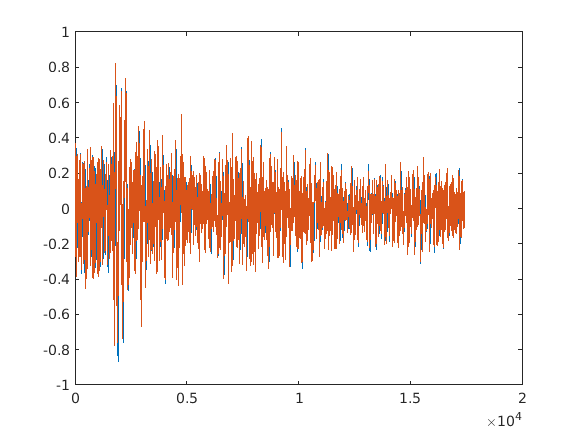

plot(y5) %plottar sista övergången

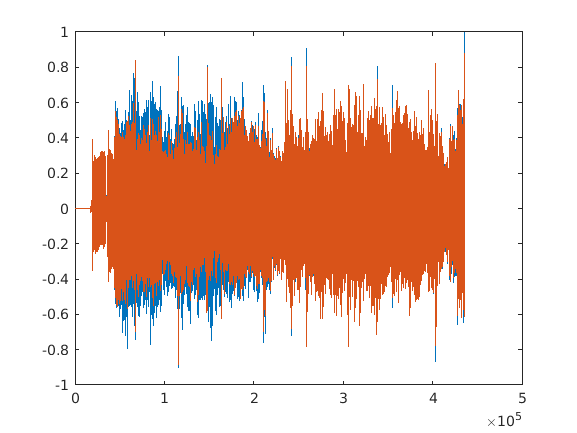

plot(y4) %plottar allt

audiowrite('crossfade.wav',y5,fs1/2); %bara själva övergången (sista övergången)
audiowrite('gitarrljudmixed.wav',y4,fs1); %hela alltihopa
